I = imread('noisyplane.tiff');

Vaihe 1:

I = double(I);
DFT = fftshift(fft2(I));

Vaihe 2:

imshow(log10(abs(DFT)), [])

DFT-spekstrissä on valkoisia pisteitä, jotka kuvaaavat jaksollista kohinaa.

Vaihe 3:

a.)

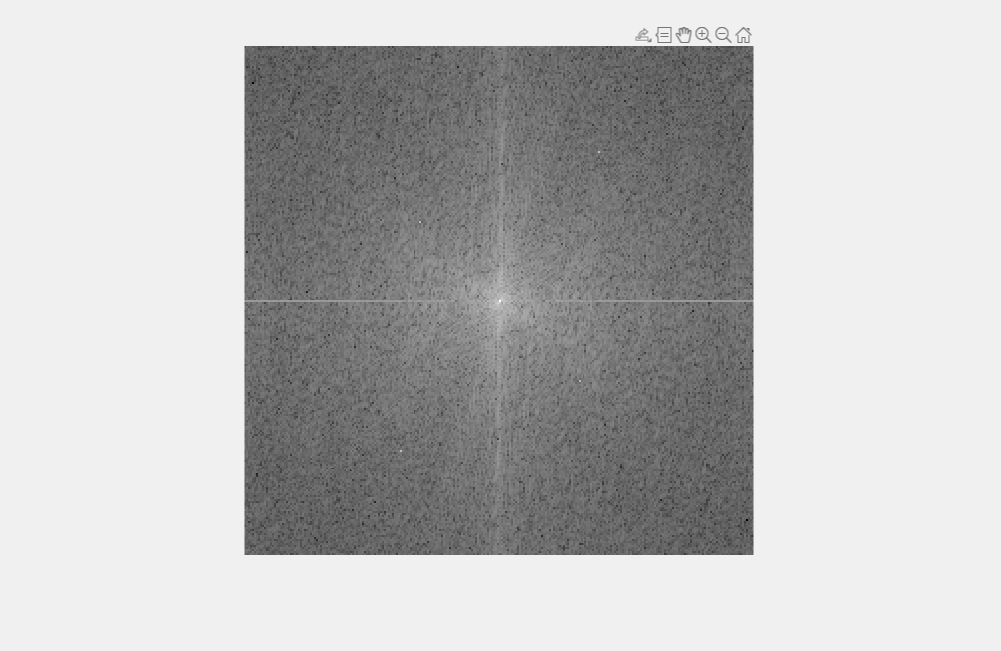

[x,y] = ginput(4);

x = round(x);
y = round(y);

alue1 = DFT(y(1)-5:y(1)+5,x(1)-5:x(1)+5);
alue2 = DFT(y(2)-5:y(2)+5,x(2)-5:x(2)+5);
alue3 = DFT(y(3)-5:y(3)+5,x(3)-5:x(3)+5);
alue4 = DFT(y(4)-5:y(4)+5,x(4)-5:x(4)+5);

b.) ja c)

[Y1,X1] = find(alue1==max(max(alue1(:))));
[Y2,X2] = find(alue2==max(max(alue2(:))));
[Y3,X3] = find(alue3==max(max(alue3(:))));
[Y4,X4] = find(alue4==max(max(alue4(:))));
X = [X1, X2, X3, X4];
Y = [Y1, Y2, Y3, Y4];

for i=1:4
    DFT(y(i)+Y(i)-6, x(i)+X(i)-6) = 0;
end

Vaihe 4:

I2 = ifft2(fftshift(DFT));

Vaihe 5:

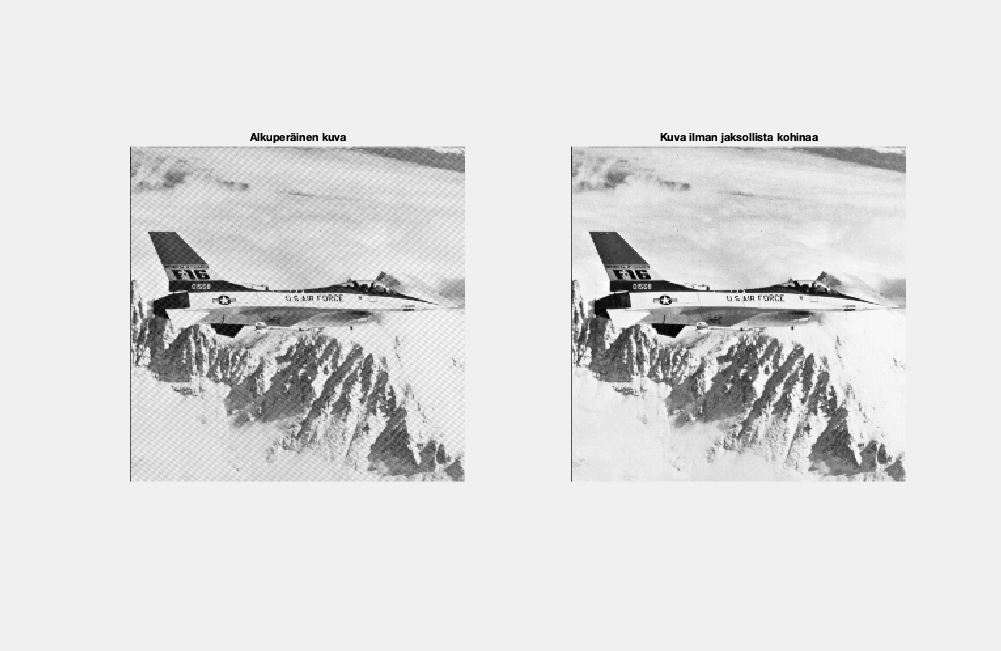

I2 = uint8(real(I2));

subplot(1, 2, 1)
imshow(I, [])
title('Alkuperäinen kuva')
subplot(1, 2, 2)
imshow(I2, [])
title('Kuva ilman jaksollista kohinaa')